## 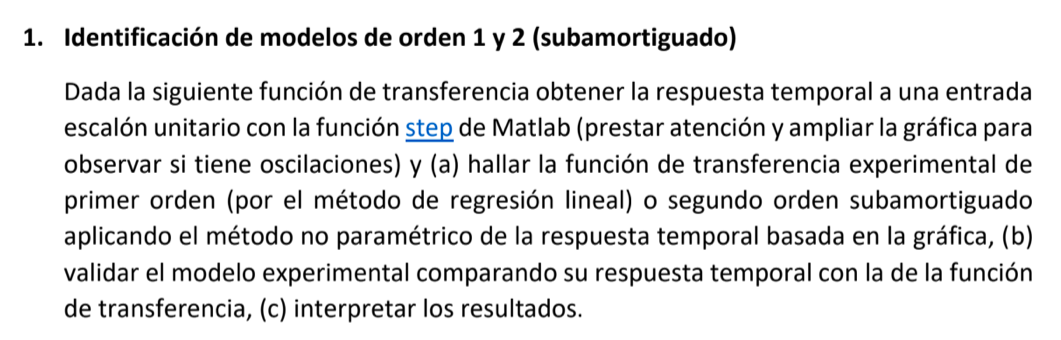

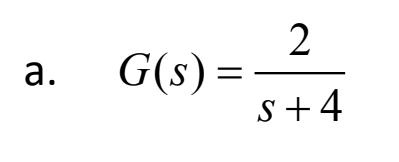ritm

clear;clc;close all
G1 = tf([2],[1 4])

G1 =
 
    2
  -----
  s + 4
 
Continuous-time transfer function.



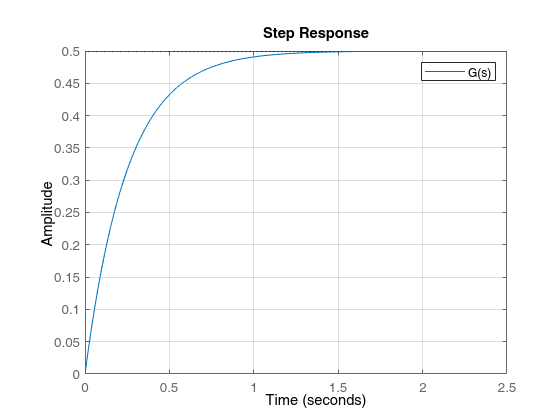

figure(1)
clf
step(G1)
grid on
legend({'G(s)'})

[y,t]=step(G1);%recolectamos los datos tal y como los arroja matlab
k= y(end)-y(1);%valor de k según la fórmula dado que la entreda al inicio es 0

**Método de regresión**

[p,s]=polyfit(t,log(1-y/(k+eps)),0);%regresión lineal al logaritmo de y
T=-1/p(1);%valores de parámetros  T y tau según las fórmulas
tf_est=tf(k/T,[1 1/T])%función de transferencia resultante

tf_est =
 
    2.397
  ---------
  s + 4.794
 
Continuous-time transfer function.



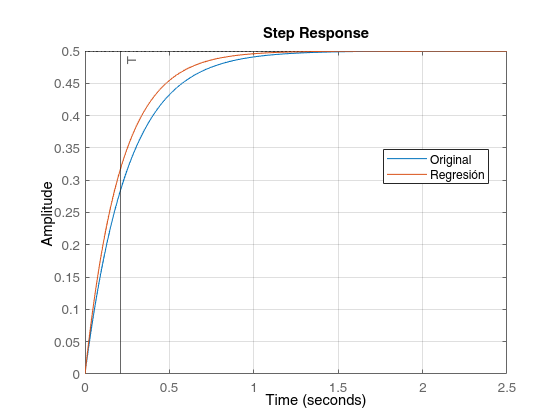

figure(1)
hold on
step(tf_est)
xline(T,'-',{'T'})
legend({'Original','Regresión'},'Location','best')

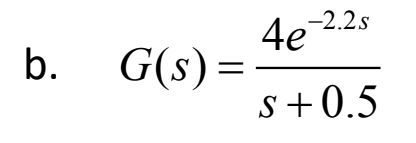

clear;clc;close all
G1 = tf([4],[1 0.5],"InputDelay",2.2)

G1 =
 
                   4
  exp(-2.2*s) * -------
                s + 0.5
 
Continuous-time transfer function.



figure(2)
clf
step(G1)
grid on
legend({'G(s)'})
[y,t]=step(G1);%recolectamos los datos tal y como los arroja matlab
inicio=find(y>0,01);%identificamos el dato a partir del cual el modelo responde a la entrada
yvals=y(inicio:end);%valores útiles de y
tvals=t(inicio:end);%valores útiles de t
k= ceil(yvals(end)-y(1)); %valor de k según la fórmula dado que la entreda al inicio es 0

**Método de regresión**

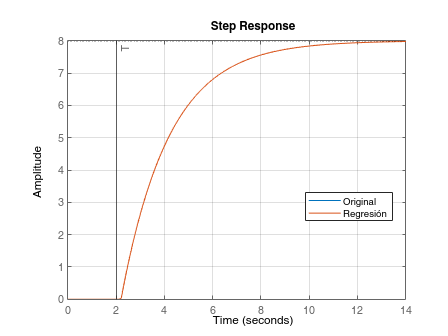

tf_est =
 
                   8
  exp(-2.2*s) * -------
                2 s + 1
 
Continuous-time transfer function.



[p,s]=polyfit(tvals,log(1-yvals/(k)),1);%regresión lineal al logaritmo de y
T=-1/p(1); tau=-p(2)/p(1); %valores de parámetros  T y tau según las fórmulas
tf_est=tf(k,[T 1],"InputDelay",tau)%función de transferencia resultante

figure(2)
hold on
step(tf_est)
xline(T,'-',{'T'})
legend({'Original','Regresión'},'Location','best')

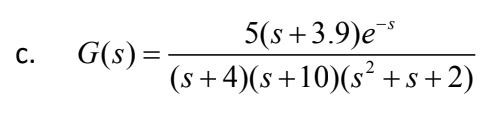

%SIstema de orden 4???? regresion?

clear;clc;close all
G1 = zpk([-3.9],[-4, -10, -(0.5 + 1.32287*i),-( 0.5-1.32287*i)],5,'InputDelay',1)

G1 =
 
                      5 (s+3.9)
  exp(-1*s) * --------------------------
              (s+4) (s+10) (s^2 + s + 2)
 
Continuous-time zero/pole/gain model.



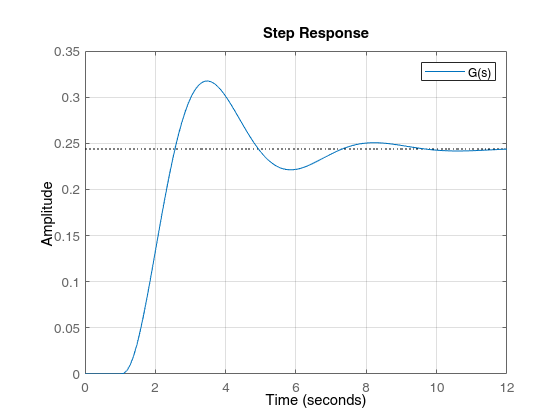

figure(1)
clf
step(G1)
grid on
legend({'G(s)'})

[y,t]=step(G1);%recolección de datos por recomendación de MatLab
inicio=find(y>0,1);%dato a partir del cual el sistema reacciona
tau=t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 1.0131

deltaY=y(end)-y(1)%delta de y por definición

deltaY = 0.2430

Mp=max(y)-y(end);%sobreimpulso máximo por definición
Tp=t(y==max(y))-tau;%tiempo de pico, se le debe restar el retardo
zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)

zeta = 0.3521

%zeta=-log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)
omega0=pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 1.3497

tf_est=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tf_est =
 
                         0.4427
  exp(-1.01*s) * ----------------------
                 s^2 + 0.9504 s + 1.822
 
Continuous-time transfer function.



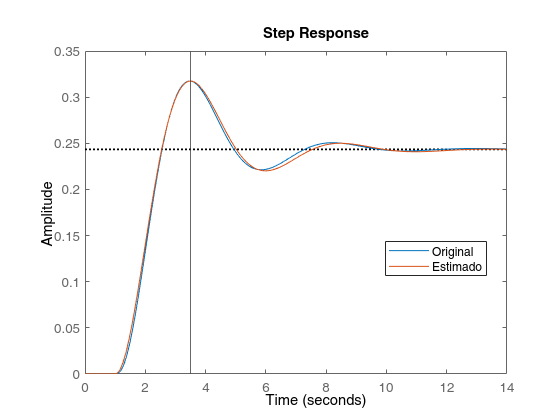

figure(2)
clf
step(G1)
hold on
step(tf_est)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

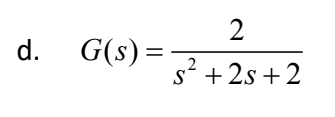

clear;clc;close all
G1 = tf(2,[1 2 2])

G1 =
 
        2
  -------------
  s^2 + 2 s + 2
 
Continuous-time transfer function.



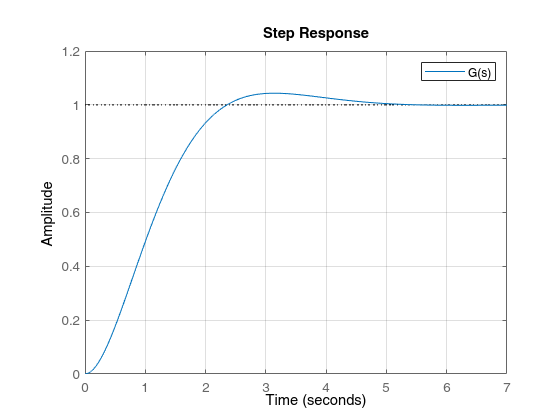

figure(1)
clf
step(G1)
grid on
legend({'G(s)'})

[y,t]=step(G1);%recolección de datos por recomendación de MatLab

deltaY=y(end)-y(1)%delta de y por definición

deltaY = 0.9981

Mp=max(y)-y(end);%sobreimpulso máximo por definición
Tp=t(y==max(y));%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta=-log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.7023

omega0=pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 1.4093

tf_est=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2])%función de transferencia estimada

tf_est =
 
         1.982
  --------------------
  s^2 + 1.98 s + 1.986
 
Continuous-time transfer function.



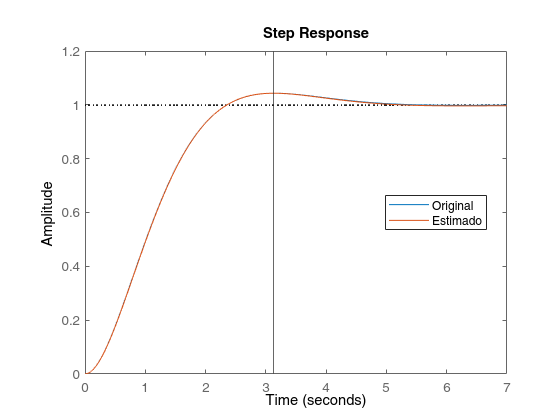

figure(2)
clf
step(G1)
hold on
step(tf_est)
xline(Tp)
legend({'Original','Estimado'},'Location','best')

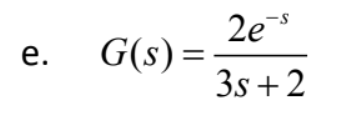

clear;clc;close all
G1 = tf([2],[3 2],"InputDelay",1)

G1 =
 
                 2
  exp(-1*s) * -------
              3 s + 2
 
Continuous-time transfer function.



figure(2)
clf
step(G1)
grid on
legend({'G(s)'})
[y,t]=step(G1);%recolectamos los datos tal y como los arroja matlab
inicio=find(y>0,05);%identificamos el dato a partir del cual el modelo responde a la entrada
yvals=y(inicio:end);%valores útiles de y
tvals=t(inicio:end);%valores útiles de t
k= yvals(end)-y(1);%valor de k según la fórmula dado que la entreda al inicio es 0

**Método de regresión**

[p,s]=polyfit(tvals,log(1-yvals/(k+eps)),1);%regresión lineal al logaritmo de y
T=-1/p(1); tau=-p(2)/p(1); %valores de parámetros  T y tau según las fórmulas
tf_est=tf(k,[T 1],"InputDelay",tau)%función de transferencia resultante

tf_est =
 
                   0.9966
  exp(-1.82*s) * -----------
                 1.029 s + 1
 
Continuous-time transfer function.



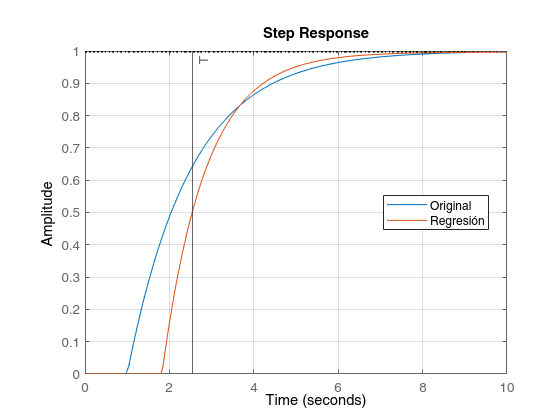

figure(2)
hold on
step(tf_est)
Tgraph = t(find(y>=y(end)*0.6317));
xline(Tgraph(1),'-',{'T'})
legend({'Original','Regresión'},'Location','best')

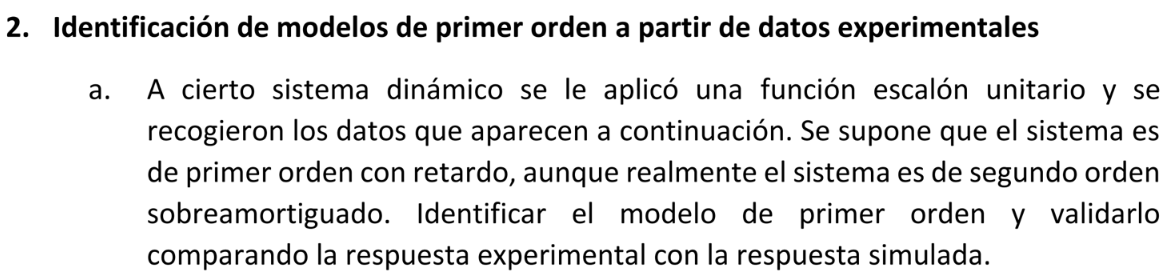

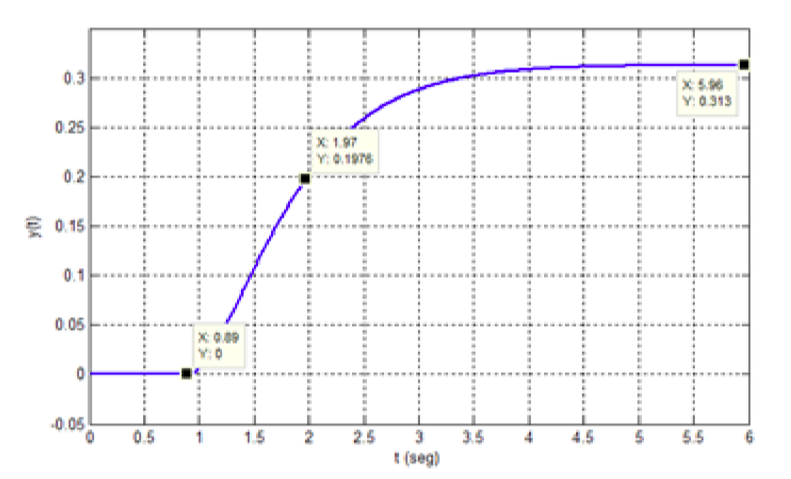

clear;clc;close all
T=1.97; tau = 0.89;
valT = T - tau;
k = 0.313

k = 0.3130

tf_est=tf(k,[valT 1],"InputDelay",tau)%función de transferencia resultante

tf_est =
 
                   0.313
  exp(-0.89*s) * ----------
                 1.08 s + 1
 
Continuous-time transfer function.



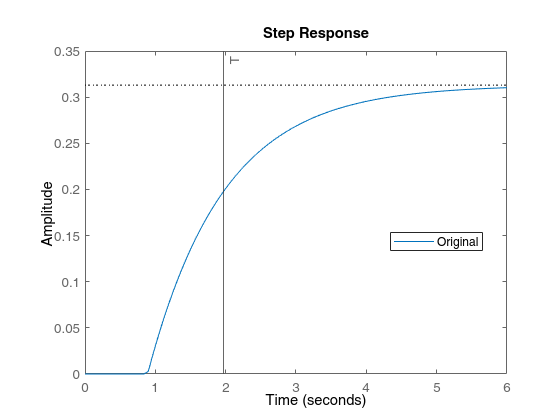

figure(3)
step(tf_est,6)
hold on
xline(T,'-',{'T'})
legend({'Original'},'Location','best')

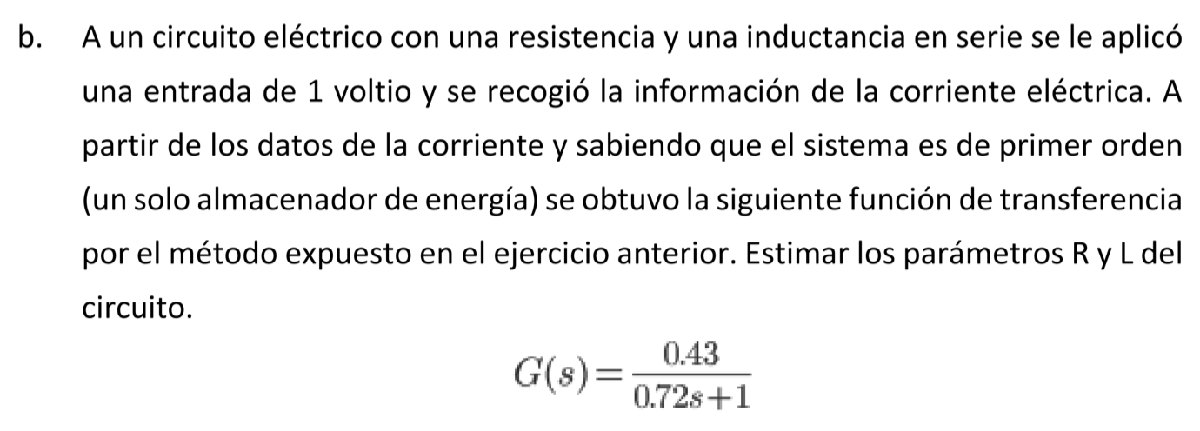

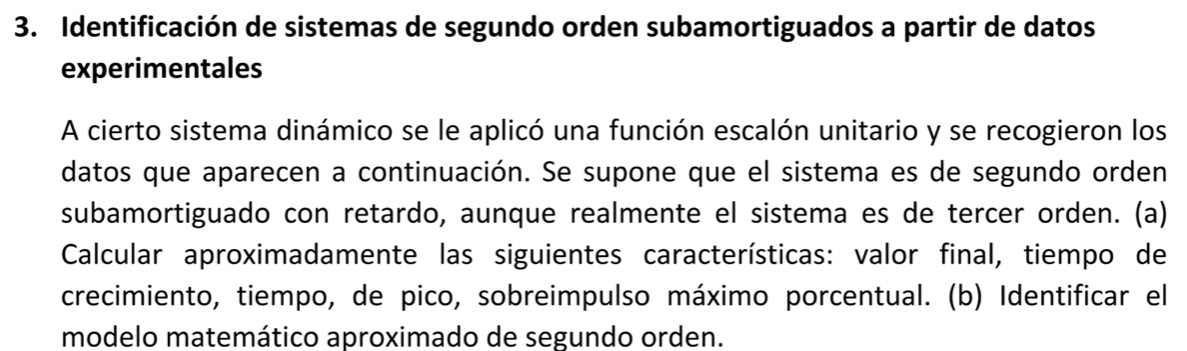

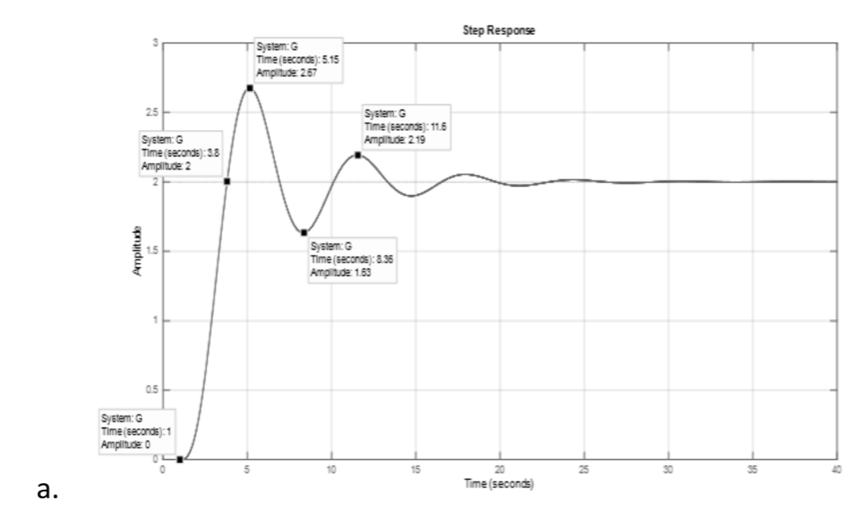

Mp = 2.67 - 2

Mp = 0.6700

tau = 1;
deltaY = 2;
Tp = 5.15-tau;
zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)

zeta = 0.3288

%zeta=-log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)
omega0=pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 0.8016

tf_est=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tf_est =
 
                      1.285
  exp(-1*s) * ----------------------
              s^2 + 0.527 s + 0.6425
 
Continuous-time transfer function.



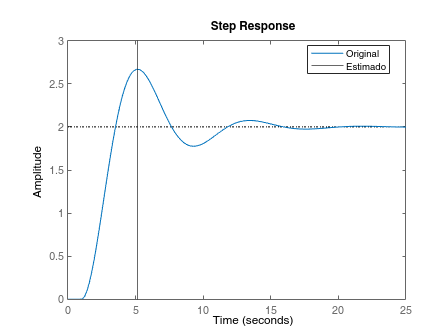

figure(3)
clf
grid on
step(tf_est)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

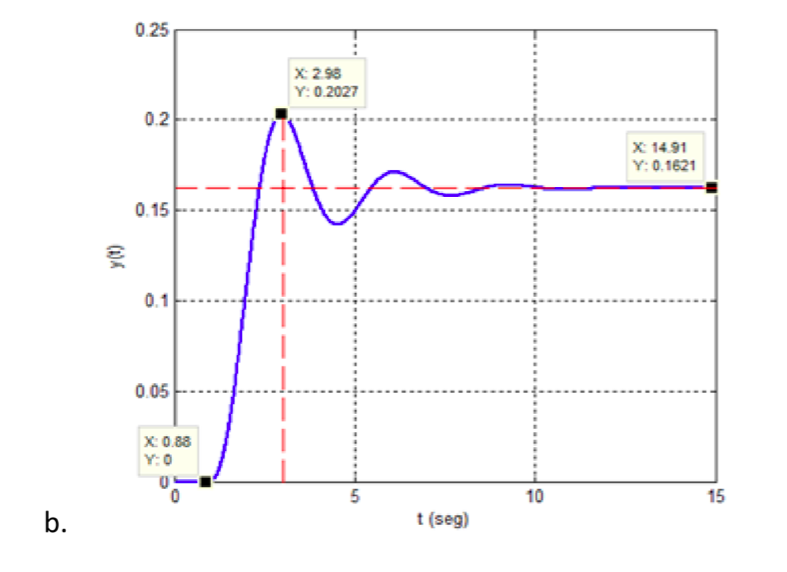

*Ajuste modelo segundo orden*

tau = 0.88;%tiempo a partir del cual el sistema reacciona
deltaY = 0.1621 - 0;%delta de y por definición
Mp = 0.2027 - 0.1621;%sobreimpulso máximo pode definición
Tp = 2.98 - tau;%tiempo de pico, se le debe restar el retardo
%zeta = -log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)
zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)

zeta = 0.4033

Como 0<zeta<1, sistema es subamortiguado

omega0 = pi/(Tp*sqrt(1-zeta^2));%valor de omega0 por fórmulas
tfEstimada = tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tfEstimada =
 
                        0.4332
  exp(-0.88*s) * ---------------------
                 s^2 + 1.319 s + 2.673
 
Continuous-time transfer function.



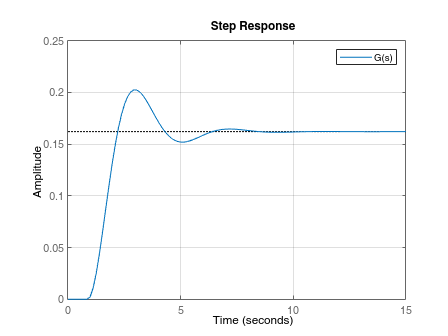

tiempofinal = 15;
clf
figure(15)
step(tfEstimada,tiempofinal)
grid on
legend({'G(s)'})

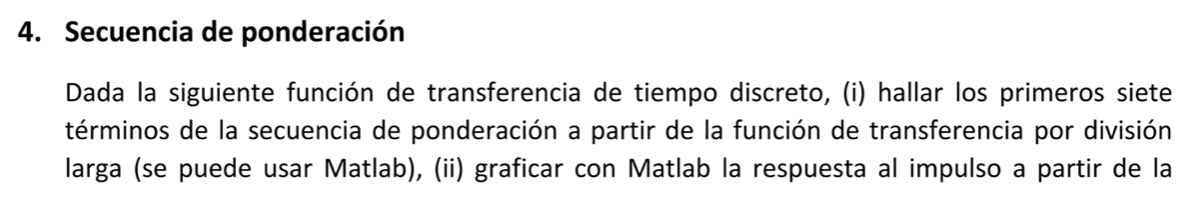    

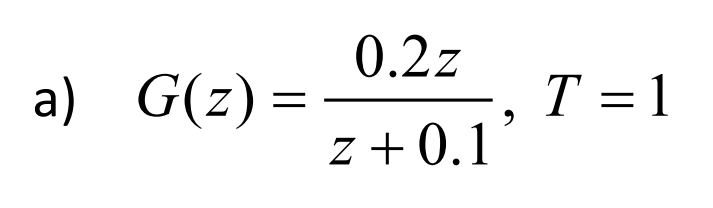

clear;clc;close all
N=1950;%número de muestras
M=10;%Longitud secuencia de ponderación
noise=0.1;%amplitud del ruido
num=[0.2];%numerador de la tf
den=[1 0.2];%denominador de la tf
tf1=tf(num,den,1)%función de transferencia objetivo

tf1 =
 
    0.2
  -------
  z + 0.2
 
Sample time: 1 seconds
Discrete-time transfer function.



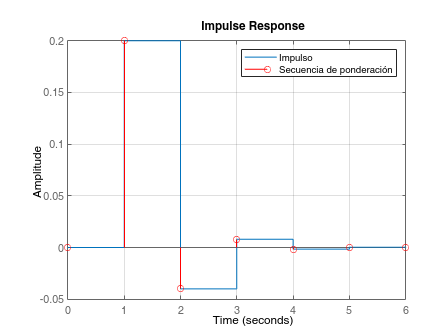

L = 7; %longitud de la secuencia de ponderación
delay = length(den)-length(num);
Secuencia = ldiv(num,den,L-delay); %división larga
Secuencia = [zeros(1,delay) Secuencia];  %secuencia con retardo agregado
clf
impulse(tf1,0:1:L-1); %impulso
hold on
stem(0:1:L-1, Secuencia,'r')
grid on
legend({'Impulso','Secuencia de ponderación'})

clf
step(Ga,0:1:L-1);
hold on
respuesta = cumsum(Secuencia.*ones(1,L));
stairs(0:1:L-1, respuesta, 'r')
legend({'Step','Entrada u=1'})

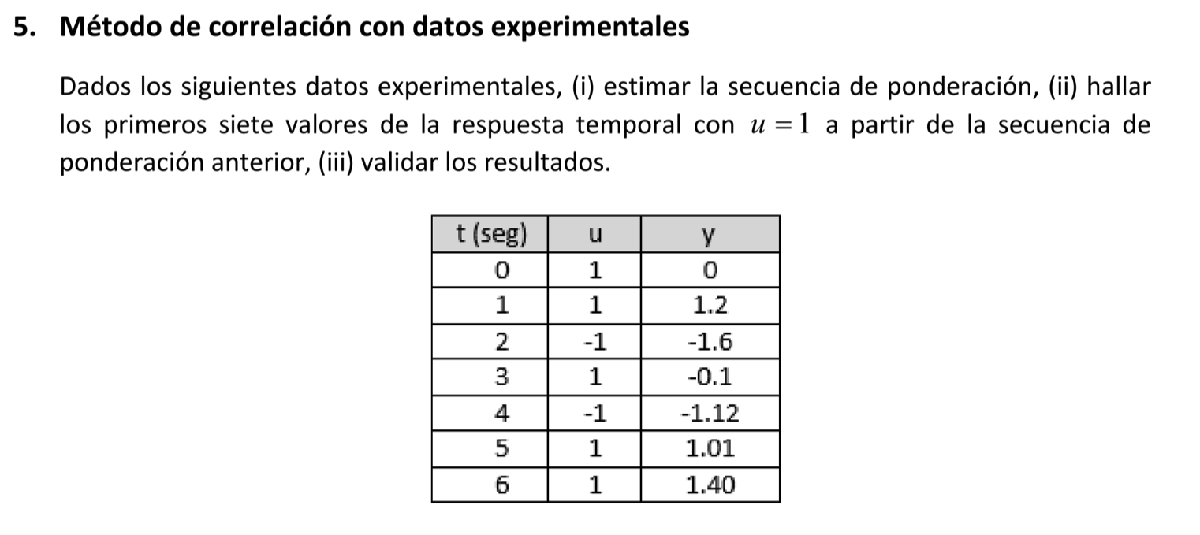

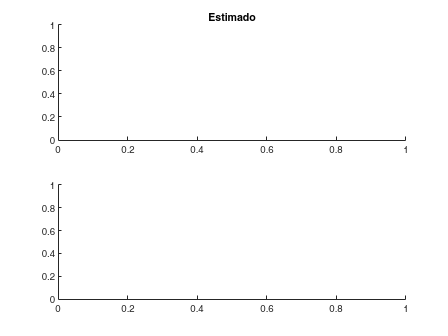

clear all
t = 0:1:6;
u = [1,1,-1,1,-1,1,1]';
y = [0,1.2,-1.6,-0.1,-1.12,1.01,1.4]';
M = 7;
N = 7;
[cyu,lagsyu] = xcorr(y,u,M-1);%M elementos de la correlación entre y y u
[cu,lagsu] = xcorr(u,0);%correlación de la entrada con ella misma en el instante 0
tf_est=cyu(lagsyu>=0)./(N:-1:N-M+1)'/(cu/N);%fórmula para la secuencia de ponderación
delay=1;%cálculo del retardo del sistema
pdata=0:1:M-1;
yE}
st = zeros(7,1);

for c=2:N
    for d=1:c-1
        yEst(c) = yEst(c) + u(c-d)*tf_est(d);
    end
end
figure(3)
clf
subplot(2,1,1)
title('Estimado')
subplot(2,1,2)